%Number 1
% newtones(f,fPrime,3,.005,50);
% Functions implemented below

%Number 2
% secant(f,1,2,.005,10);
%Functions implemented below

%Number 3a
f = @(x) (x^2) - 2;
fPrime = @(x) 2*x;

g1 = newtones(f,fPrime,3,eps(),10,1.41421);
g2 = secant(f,1,2,eps(),100,1.41421);

The procedure was successful, p is: 1.4142

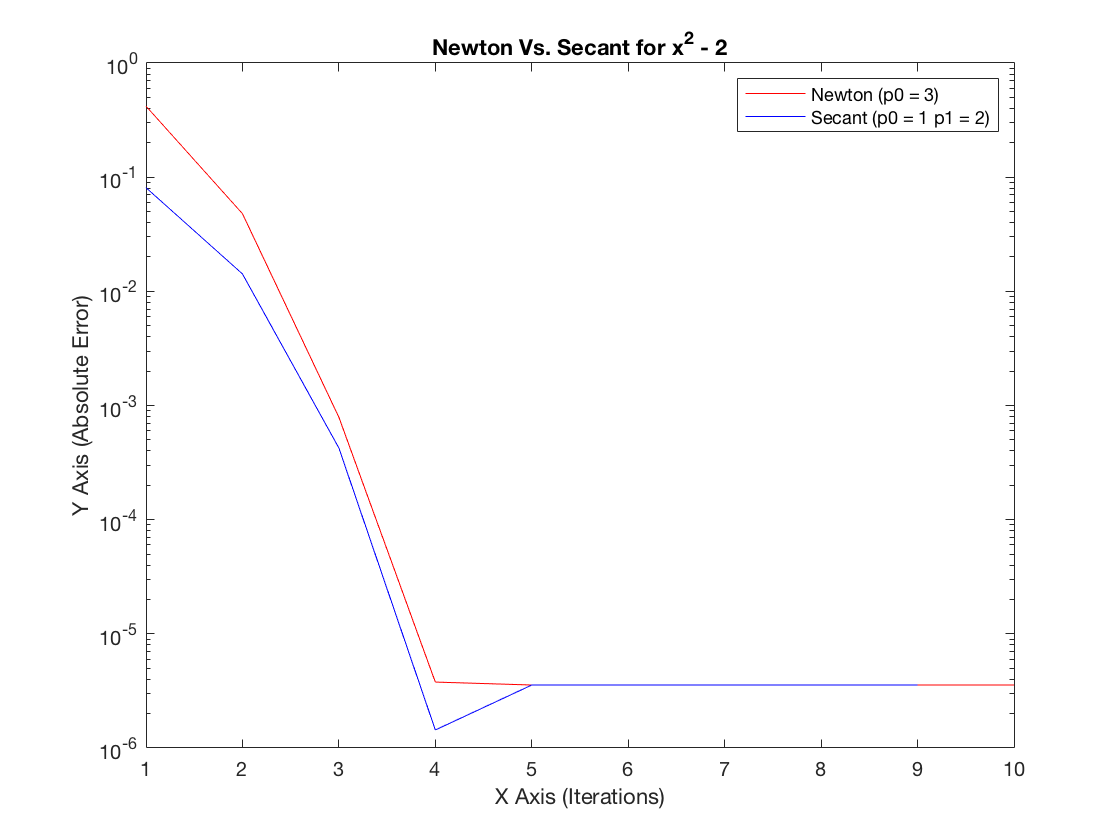

semilogy(1:10,g1,'r')
hold on 
semilogy(1:9,g2,'b');
hold off
title('Newton Vs. Secant for x^2 - 2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Absolute Error)');
legend('Newton (p0 = 3)','Secant (p0 = 1 p1 = 2)');

%Number 3b
syms x
f = @(x) tanh(x);
df = diff(f(x));
if isempty(symvar(df))
  fPrime = str2func(['@(x) repmat(', char(df), ', size(x))'])
else
  fPrime = matlabFunction(df);
end
%Anything higher than 1.08 will give errors
g1 = newtones(f,fPrime,1.08,eps(),9,0);

The Procedure was sucessful. p is: 0


g2 = secant(f,-1,2,eps(),9,0);

The procedure was successful, p is: 0

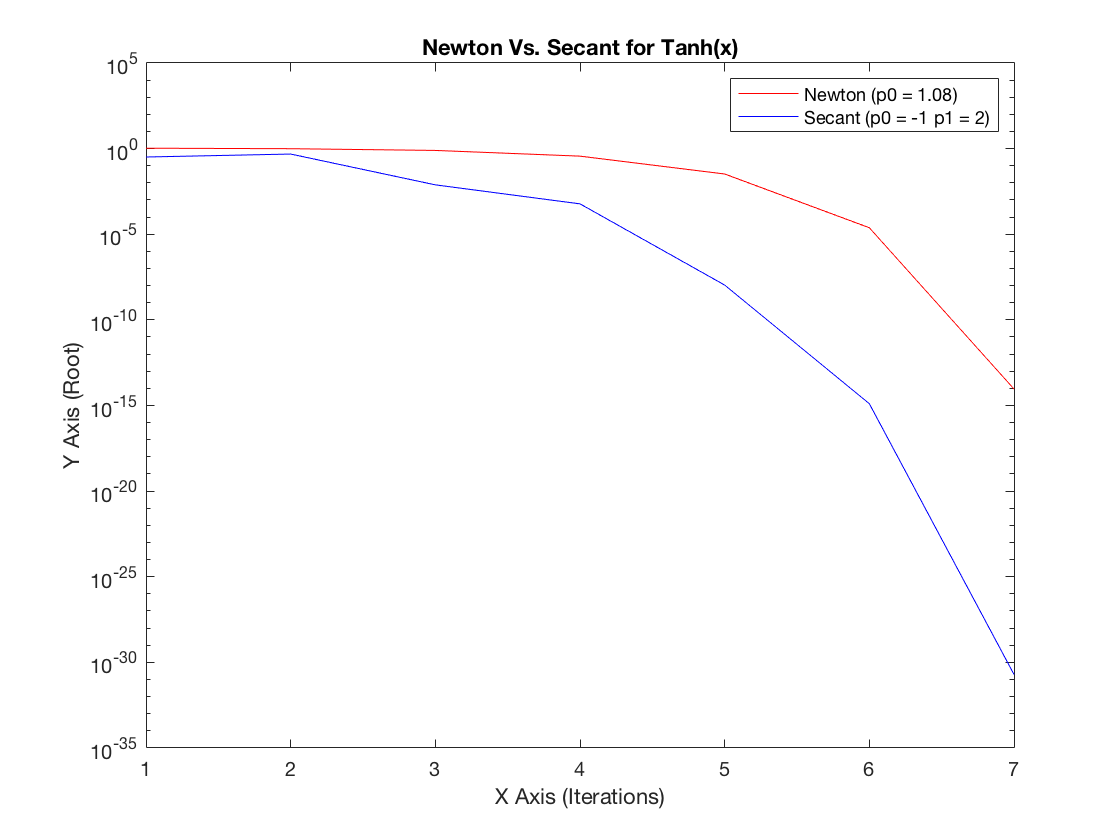

semilogy(1:9,g1,'r')
hold on 
semilogy(1:8,g2,'b');
hold off
title('Newton Vs. Secant for Tanh(x)');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 1.08)','Secant (p0 = -1 p1 = 2)');

%When p0 = 0 or 1 in Newtones, it oscilates between 0 and 1
%Number 3c
f = @(x) (x^3-2*x+2);
fPrime = @(x) 3*x^2 -2;
%When p0 = 0 or 1 in Newtones, it oscilates between 0 and 1
g1 = newtones(f,fPrime,3,eps(),50,-1.759);

The Procedure was sucessful. p is: -1.7693


g2 = secant(f,-1,1,eps(),50,-1.769);

The procedure was successful, p is: -1.7693

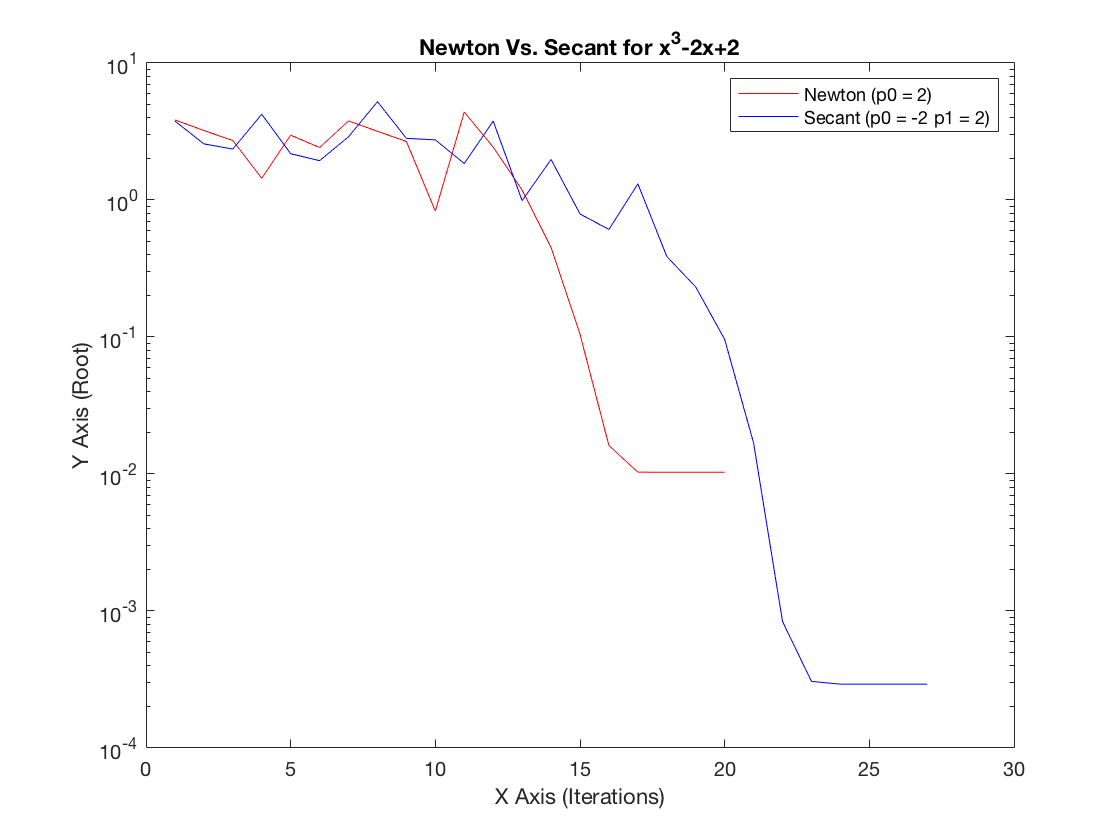

semilogy(1:20,g1,'r')
hold on 
semilogy(1:27,g2,'b');
hold off
title('Newton Vs. Secant for x^3-2x+2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 2)','Secant (p0 = -2 p1 = 2)');

% %Number 3d
f = @(x) x^(1/3);
fPrime = @(x) (1/3) * x^(-2/3);
g1 = newtones(f,fPrime,2,eps(),100,0);
g2 = secant(f,-2,2,eps(),100,0);

The output failed, we need more than 101 iterations

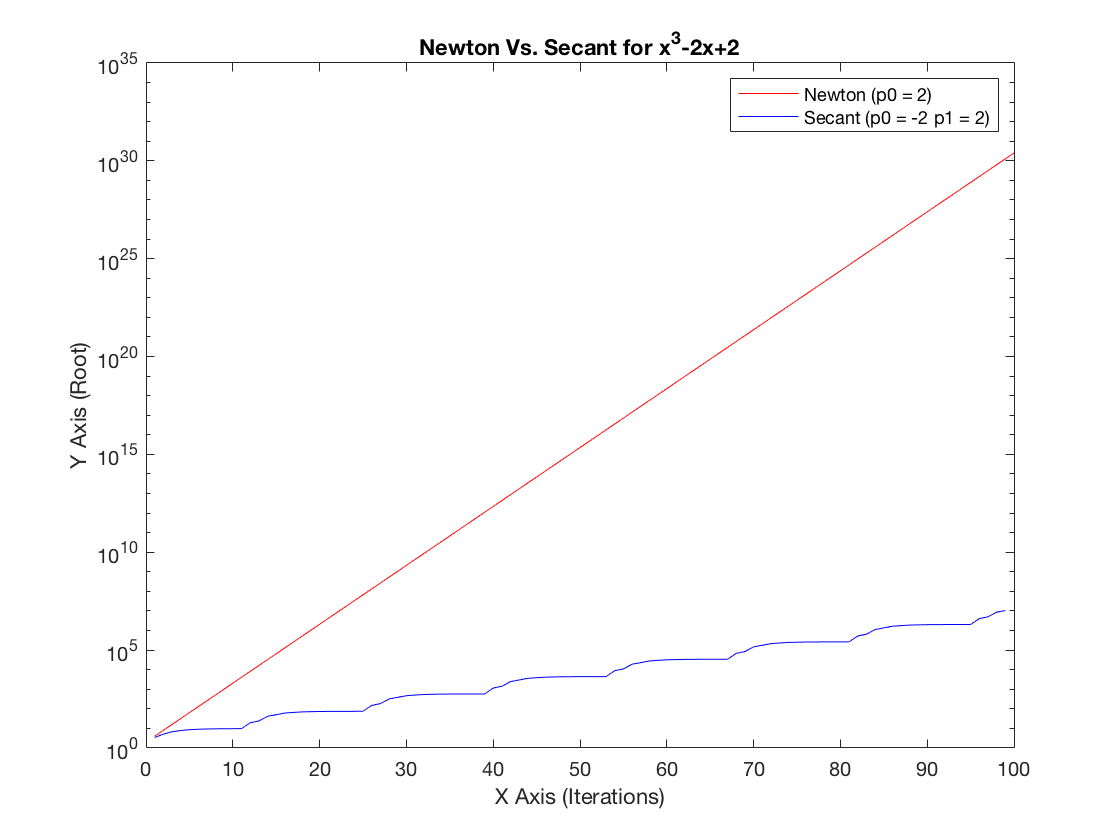

semilogy(1:100,g1,'r')
hold on 
semilogy(1:99,g2,'b');
hold off
title('Newton Vs. Secant for x^3-2x+2');
xlabel('X Axis (Iterations)');
ylabel('Y Axis (Root)');
legend('Newton (p0 = 2)','Secant (p0 = -2 p1 = 2)');

function p = newtones(f,fPrime,p0,tol,maxits,root)
format long;
    i = 1;
    while (i <= maxits)
        p = p0-f(p0)/fPrime(p0);
        g(i) = abs(root-p);
        if (abs(p-p0) < tol)
            fprintf("The Procedure was sucessful. p is: " + p + "\n");
            g(i) = abs(root-p);
            break;
        end 
%       fprintf("The current value at p is: " + p +  " iteration " + i +"\n");
        i = i+1;
        p0 = p;
    end 
    p = g;
end

function p = secant(f, p0, p1, tol, maxits,root)
format long;
    i = 2;
    q0 = f(p0);
    q1 = f(p1);
    while (i <= maxits)
        p = p1-(q1*(p1-p0))/(q1-q0);
        g(i-1) = abs(root-p);
        if (abs(p-p1) < tol)
            fprintf("The procedure was successful, p is: " + p);
            g(i-1) = abs(root-p);
            break;
        end
%         fprintf("We are on iteration " + i + "\n");
        i = i+1;
        p0 = p1;
        q0 = q1;
        p1 = p;
        q1 = f(p);
        if i > maxits
            fprintf("The output failed, we need more than " + i +" iterations");
        end
    end
    p = g;
end
